# Stability analysis for continuous control systems 

The script reviews the main concepts of stability analysis of continuous systems using common tolls such as pole-zero positions, the root locus method, Nyquist criterion  and Bode diagrams. It then focuses on how tools in the control toolbox can be used to support this analysis. Hence, the aim of this file is to summarise briefly several methods and then illustrate the matlab tools for analysing stability. Use other resources to learn more detail on the methods; here we assume familiarity as the focus is on MATLAB.

### Resources and similar files in the toolbox

**Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019**

See website below for more files like this.     

[Modelling, Dynamics and Control - Section six: Behaviour characterisation for any order system ](https://sites.google.com/sheffield.ac.uk/controleducation/chaptermodelling/sectionmodellingbehaviours)

[Modelling, Dynamics and Control - Chapter four: Classical control design techniques ](https://sites.google.com/sheffield.ac.uk/controleducation/chapterclassical)[https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

Design procedures ensuring stability and also prescribed quality specifications are discussed in the files: 

***proportional_design_with_bode.mlx,***  ***lag_design_with_bode.mlx,*** ***lead_design_with_bode.mlx, lead_lag_design_with_bode.mlx, PID_Cont_Controller_Design_with_Pole_Cancellation, discrete_models_and_discrete_PID_controller_design.***

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Ruth Bars and Gyula Max, Budapest University of Technology and Economics with edits from  J.A. Rossiter, University of Sheffield 

             

## Table of contents

- Background and the concept of stability

- Mathematical formulation of stability of a closed loop control system

- Analysing the pole-zero map

- Root locus method

- Nyquist stability criterion

- Practical stability measures

- Examples

## 1. Background and the concept of stability

Control systems are based on negative feedback. In a simple control loop the reference signal is compared to the measured output signal. The error signal provides the input of the controller. The output of the controller is the input of the system to be controlled (see the figure below). It should be ensured that the output of the system tracks the reference signal after deceasing of the transients.

         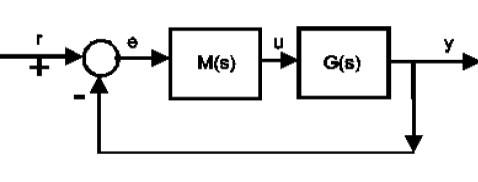

Quality specifications are set for the control system. As the signal flow in the system needs time, achieving a steady state must be ensured. Because of the delays and amplifications in the individual elements the settling of the output signal is not always ensured. No steady or increasing oscillations are allowed. This means that the control system should be stable. One formulation of stability is that for convergent reference signal the output signal should be also convergent.

Tracking should be ensured with a prescribed accuracy if the steady state has been already reached. There are prescriptions also for the transient process as settling time, overshoot, etc. Quality specifications can be formulated in the time domain and also in the frequency domain.

One of the most important properties of linear control systems is stability. A general formulation of stability says that a system is stable if removing it from a stable state the system returns to the original state providing no external input is applied. Another formulation of stability is called BIBO stability, i.e. bounded inputs result in bounded outputs in case of stable systems. Or as mentioned above for convergent reference signal the output signal should be also convergent.

Stability of a control system has to be distinguished from the stability of the process itself. Irrespective of whether the process itself is stable or unstable, using a proper control system the closed loop system may become stable. There are several methods to check the stability of a control system. 

Some methods just give evaluation whether the system is stable or not, while other methods provide measures how far is the system from the boundary of stability. These measures can be used for controller design ensuring stability and also the prescribed quality specifications (see the referred files above).

## 2. Mathematical formulation of stability of a closed loop control system

Consider the closed-loop system given in the figure below. The open-loop transfer function is *L(s)=M(s)G(s)*, and a unity feedback is applied around it.

                 

The overall transfer function of the closed-loop system between the output y(t) and the reference signal r(t) is:

                   
$$T\left(s\right)=\frac{L\left(s\right)}{1+L\left(s\right)}$$
            

(See also file ***closedloop_transferfunctions_with_feedback.mlx  ***deriving how to receive closed loop transfer functions.)

A continuous LTI systems is stable if all the poles of its transfer function are located on the left half of the complex plane, that is,  all the components of the transient response will decay once the roots of the characteristic equation $1+L\left(s\right)=0\;$ are  located on the left-hand side of the complex plane. The characteristic equation is the denominator polynomial of the closed-loop transfer function above. Consequently, roots of the characteristic equation are identical to the poles of the closed-loop system.  

## 3. Analysing the pole-zero map

One way to obtain the system output in analytical form is to derive the partial fractional expansion form of the transfer function. Then the output signal in the time domain is obtained by performing the inverse Laplace transformation of the components and summarizing them. The inverse Laplace transform of components with real poles is obtained as

$L^{-1} \left(\frac{a}{s+b}\right)=a\cdot e^{-b\cdot t}$  or  $L^{-1} \left(\frac{a}{s-b}\right)=a\cdot e^{b\cdot t}$

where b>0. While the first function decays, the second function diverges. Thus a pole located on the left side of the complex plane ensures stable, while a pole located on the right side gives unstable behaviour.

Consequently, system stability can be determined based on the location of the system poles (the roots of the characteristic equation). A system turns out to be stable once all the poles are located on the left-hand side of the complex plane. If oscillating components show up, complex conjugate left-half plane poles indicate that. (See also file ***transferfunctions_and_behaviours.mlx*** which shows the link between poles and behaviours.)

So it is very easy to check system stability with a pole-zero map of the closed loop transfer function.

***Remark***: Stability can be analysed also analytically using the Routh scheme or the Hurwitz determinant which build a scheme of the coefficient of the differential equation and from this determine whether there are left side poles or not. Not discussed here.

## 4. Root locus method

Root-locus is a graphical-analytical method to show how the poles of the closed-loop system  change while one parameter (typically the loop gain) in the system is changing from zero to infinity. Note that zero loop gain relates to the open-loop system. 

If the poles (the roots of the characteristic equation) are located on the left side of the complex plane, the closed-loop system is stable. If the poles lie on the imaginary axis, the closed-loop system is on the borderline of stability and there are oscillations of steady amplitude in the control system.  Right side poles mean unstable behaviour. The root locus is not just able to judge closed-loop stability, but also exhibits information on the dynamics of the closed loop system. Root locus points on the negative real axis suggest well damped transients in the time domain, while root locus points with complex poles on the left-hand side on the complex plane refer to oscillating behaviour associated to under-damping. Hence, the root locus shows how the change of the considered parameter influences the stability and dynamics of the closed loop control system. 

MATLAB illustrations are given in section 7 after all the introductory background so that readers can see all the different tools side by side. The ***rlocus*** command draws the root locus. The MATLAB command ***rlocfind*** is applied to find the gain belonging to a given point of the root locus. ***rlocfind*** puts up a crosshair cursor in the graphics window which is used to select a pole location on an existing root locus. Note this figure may appear outside of the livescript window.

***Remark***: The MATLAB tool ***sisotool.m*** is excellent for seeing all the traditional analysis plots and data side by side and thus for supporting design. This note focuses more on the underlying individual functions and analysis tools which allow more nuanced investigations and better plots.

## 5. Nyquist stability criterion

The Nyquist stability criterion analyses the stability of the closed loop system based on the frequency function of the open loop transfer function.  The Nyquist stability criterion is briefly summarised as follows.

a. To check the closed loop stability the simplified version of the Nyquist stability criterion can be applied if  the transfer function of the open loop has no unstable poles (poles with positive real value). The closed loop system is stable if the complete Nyquist diagram of the open loop (sketched for negative and positive frequencies) does not encircle point -1+j0 of the complex plane. 

b.To check the closed loop stability the generalized Nyquist criterion is to be applied if the open loop transfer function has unstable poles (poles with positive real value). The closed loop system is then stable if the number of the encirculations around the point -1+j0 by the complete Nyquist diagram of the open loop system is equal to the number of the unstable poles of the transfer function of the open loop. Encirculation is considered positive in counter clockwise sense. Note that the simplified Nyquist criterion is a special case of the generalized criterion. 

***Remark***: In many cases, ensuring that the phase margin is positive is sufficient as almost inevitably the Nyquist criteria is then met.

## 6. Practical stability measures

Several measures exist to characterize how far a stable system is from being unstable.  

**Phase margin** represents the value of the phase angle of the open loop frequency function at the gain cross-over frequency. More specifically, the phase margin can be expressed analytically as $\varphi_m =\varphi \left(\omega_c \right)+{180}^{\circ }$, where $\omega_c$ is the gain cross-over frequency where the absolute value of the open loop frequency function is 1.  

- The phase margin $\varphi_m$ is illustrated on the figure below.   

- The closed-loop system is stable if the phase margin $\varphi_m$ is positive (measured clockwise). 

For design purposes a $60\degree$ phase margin is a typical prescription. In this case it is expected that the overshoot of the step response of the closed loop system is less than 10%.

                           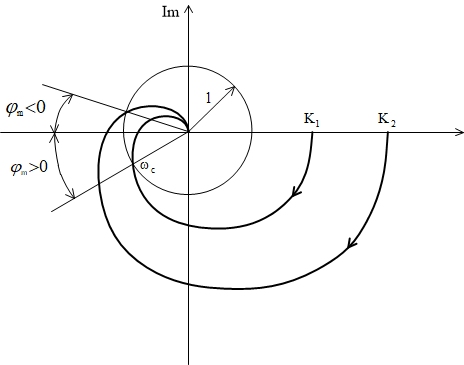

**Gain margin** is the value the loop gain is to be multipled to push the closed-loop system to borderline stability. 

  $\textrm{gm}=\frac{1}{\left|L\left(j\omega_{\pi } \right)\right|}$   where $\omega_{\pi }$  is the phase cross-over frequency where the phase angle is ${-180}^{\circ }$.

The gain margin can be read from the figure above. Read the distance between the crosspoint of the Nyquist diagram and the negative real axis and the origin and calculate its reciprocal.

The closed loop system is stable if the gain margin exceeds 1.  A reasonable design prescription for the gain margin is above 2 although its size beyond this is often not a good indicator of anything. 

**Bode diagrams**: Both phase margin and gain margin can be more easily illustrated and computed on the Bode diagrams which plot gain and phase separately. The figure below shows the phase margin and the gain margin on the Bode diagram where the vertical lines represent the gain and phase cross-over frequencies. MATLAB provides the **margin** command to produce this plot and then to calculate and plot the phase and gain margin values. 

                   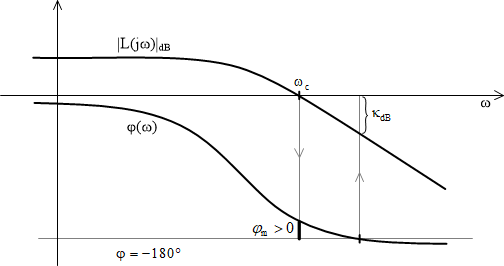

**Remark: Delay margin** defines the smallest value of the time delay needed to push the system to borderline stability. It can be calculated as follows:


$$T_{\textrm{dmin}} =\frac{\textrm{pm}\left\lbrack \textrm{rad}\right\rbrack }{\textrm{wc}\left\lbrack \frac{\textrm{rad}}{\sec }\right\rbrack }$$


The file ***proportional_design_with_bode.mlx*** uses these measures for controller design.

## 7. Examples

This section shows how the MATLAB analysis tools support feedback loop analysis and design. Spedcifically here the main focus is on  the stability of the feedback loops using the loop transfer function (system + compensator). In the control system the only variable is the proportional part of the compensator and unity feedback is applied. Specifically the examples:

- assess the closed loop poles. 

- use the root locus method.

- apply the Nyquist stability criterion. 

- consider gain and phase margins from the Bode diagrams.

#### **7.1 Example 1**

The transfer function of the open loop is

                        
$$G\left(s\right)M\left(s\right)=L_1 \left(s\right)=\frac{2}{\left(1+10s\right)\left(1+0\ldotp 48s+0\ldotp 2s^2 \right)}$$


Is this closed loop stable?

#### **7.1.1 Assessment of poles**

Analyse the stability based on the pole-zero map of the system.

The closed-loop system is stable as all the poles are on the left side of the complex plane. One can also verify that by looking at the closed-loop transfer function $T_1$. 

disp('EXAMPLE 7.1.1')

EXAMPLE 7.1.1


clear
clf
disp('The transfer function of the open loop')

The transfer function of the open loop


s=zpk('s');
L1=2/((1+10*s)*(1+0.48*s+0.2*s*s))  % stable

L1 =
 
             1
  ------------------------
  (s+0.1) (s^2 + 2.4s + 5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The transfer function of the closed loop')

The transfer function of the closed loop


T1=minreal(L1/(1+L1),0.001)

T1 =
 
                  1
  ---------------------------------
  (s+0.3318) (s^2 + 2.168s + 4.521)
 
Continuous-time zero/pole/gain model.
Model Properties



subplot(121)
pzmap(T1,'blue');
title('Pole-zero map of T1')
disp('The poles of the closed loop system')

The poles of the closed loop system


[pT1]=pzmap(T1)

pT1 =   -0.3318 + 0.0000i
  -1.0841 + 1.8290i
  -1.0841 - 1.8290i


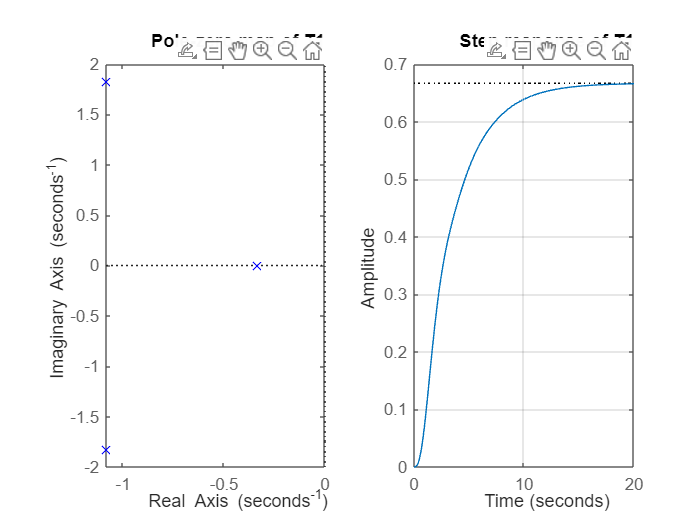


subplot(122)
step(T1),grid
title('Step response of T1')

#### 7.1.2 Using root-loci

Analyse the stability of the closed loop system and determine the critical gain based on the root locus curves. Note that:

-  the code (***rlcofind***) opens a figure in a separate window.

-  waits for you to use the crosshair to select the desired point, before the code continues to the next step.

- locate the cross on the crosspoint of the root locus and the imaginary axis and click. You may need to zoom in to be more precise.

disp('EXAMPLE 7.1.2')

EXAMPLE 7.1.2


clear
clf
disp('The transfer function of the open loop')

The transfer function of the open loop


s=zpk('s');
L1=2/((1+10*s)*(1+0.48*s+0.2*s*s))  % stable

L1 =
 
             1
  ------------------------
  (s+0.1) (s^2 + 2.4s + 5)
 
Continuous-time zero/pole/gain model.
Model Properties


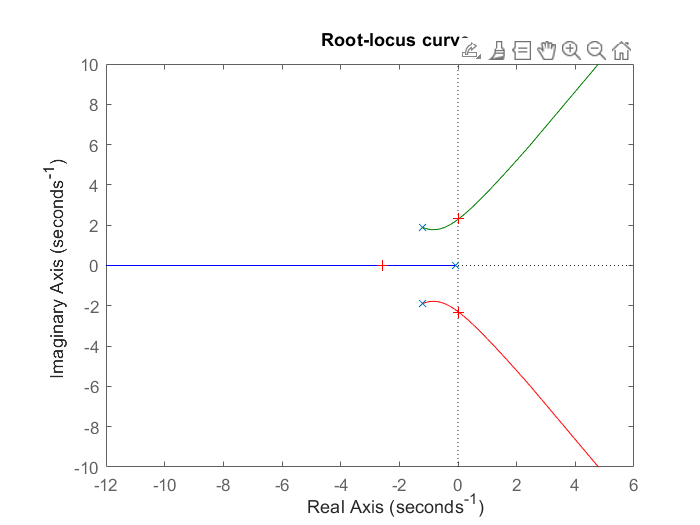

Select a point in the graphics window


selected_point = 0.0170 - 2.3325i

Kcrit1 = 13.2923

%Root locus curves
rlocus(L1)
title('Root-locus curve')
Kcrit1 = rlocfind(L1)


t=0:0.01:20;
disp('The transfer function of the closed loop')

The transfer function of the closed loop


T1=minreal(Kcrit1*L1/(1+Kcrit1*L1),0.001)

T1 =
 
               13.292
  ---------------------------------
  (s+2.559) (s^2 - 0.05873s + 5.39)
 
Continuous-time zero/pole/gain model.
Model Properties


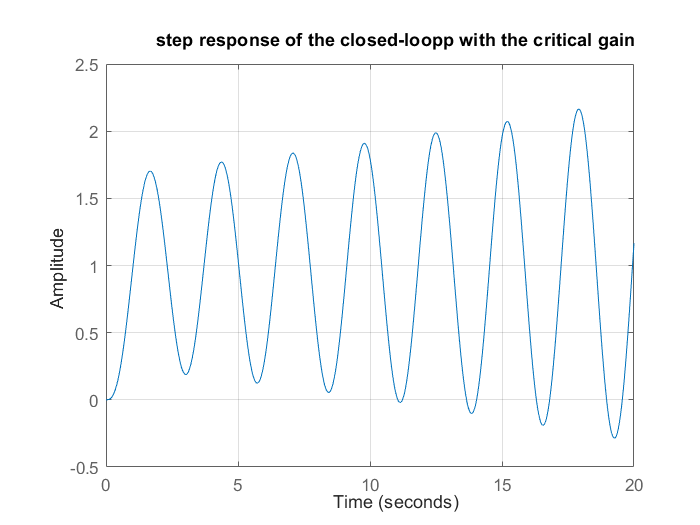

step(T1,t),grid
title('step response of the closed-loopp with the critical gain')

The critical gain is around 12.3, where steady oscillations appear in the step response of the output signal.

#### 7.1.3 Using the Nyquist stability criterion

Analyse the stability of the closed loop system and determine the critical gain based on the Nyquist stability criterion.

- The closed loop is stable as the Nyquist diagram does not encircle point -1+j0.

- To determine the critical gain, determine approximately the real value where the Nyquist diagram crosses the real axis where the imaginary value is approximately zero. The inverse of this is the critical value.

- The code below extracts the numerical values of $L\left(w\right)$so that you can find these values by manual search and thus understand the process. More systematic code is possible.

The step response plot validates that this method does indeed find the critical gain (approximately as manual).

disp('EXAMPLE 7.1.3')

EXAMPLE 7.1.3


clear
clf
disp('The transfer function of the open loop')

The transfer function of the open loop


s=zpk('s');
L1=4/((1+10*s)*(1+0.48*s+0.2*s*s))  % stable

L1 =
 
             2
  ------------------------
  (s+0.1) (s^2 + 2.4s + 5)
 
Continuous-time zero/pole/gain model.
Model Properties


w=2:0.05:2.5;
[Re,Im]=nyquist(L1,w);
omega_realL_imagL = [w' Re(:) Im(:)]

omega_realL_imagL =     2.0000   -0.1971   -0.0515
    2.0500   -0.1912   -0.0406
    2.1000   -0.1850   -0.0306
    2.1500   -0.1783   -0.0214
    2.2000   -0.1714   -0.0130
    2.2500   -0.1643   -0.0054
    2.3000   -0.1572    0.0014
    2.3500   -0.1499    0.0075
    2.4000   -0.1427    0.0128
    2.4500   -0.1356    0.0175


k=1/0.1572

k = 6.3613

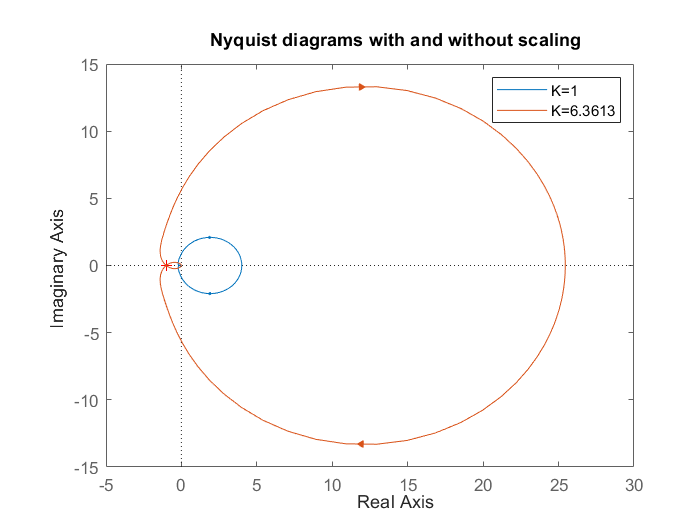


nyquist(L1,L1*k)
legend('K=1',['K=',num2str(k)])
title('Nyquist diagrams with and without scaling')

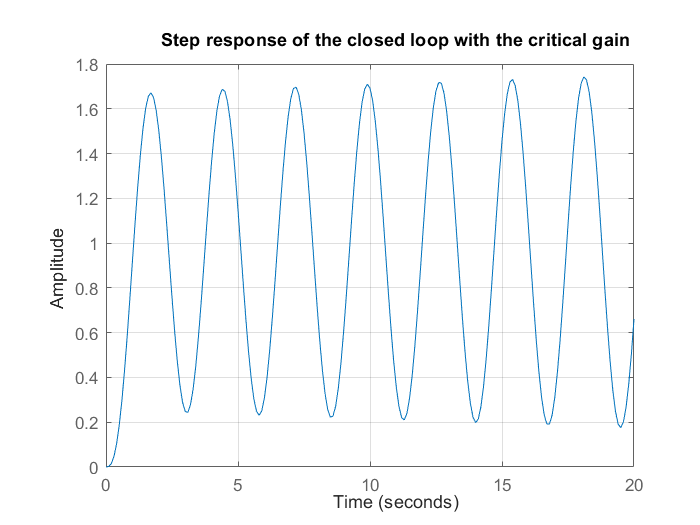



L1k=k*L1;
Tk1=minreal(L1k/(1+L1k),0.001);
t=0:0.1:20;
step(Tk1,t),grid
title('Step response of the closed loop with the critical gain')

#### **7.1.4 Using stability measures and Bode diagrams**

This section illustrates the gain and phase margins more precisely and clearly by using Bode diagrams. These also allow a better indication of expected performance.

For completeness the concept of the delay margin is also included. 

The file ***margin.m*** can be used to determine the gai and phase margin and the associated cross-over frequencies, as seen below.

- Used alone it generates a figure.

- Used with output arguments it brings data into the workspace.

disp('EXAMPLE 7.1.4')

EXAMPLE 7.1.4


clear
clf
disp('The transfer function of the open loop')

The transfer function of the open loop


s=zpk('s');
L1=2/((1+10*s)*(1+0.48*s+0.2*s*s))

L1 =
 
             1
  ------------------------
  (s+0.1) (s^2 + 2.4s + 5)
 
Continuous-time zero/pole/gain model.
Model Properties



[gm,pm,wg,wc]=margin(L1)

gm = 12.6003

pm = 115.1183

wg = 2.2891

wc = 0.1738

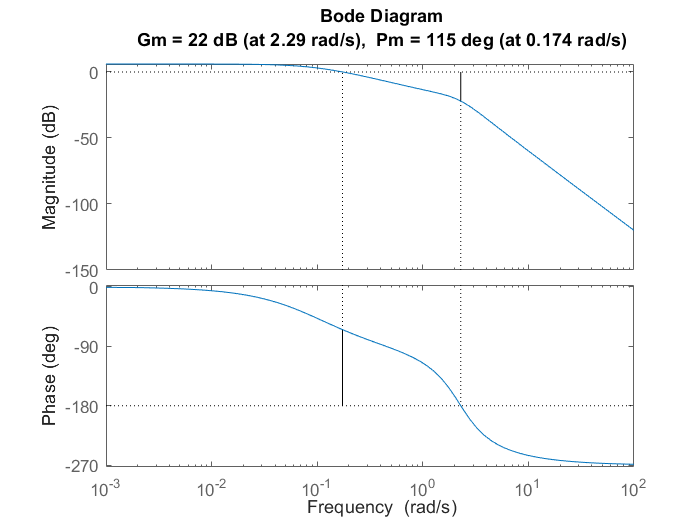

margin(L1)

The inverse of the gain margin is the critical gain; this can be illustrated easily.

Tcrit=minreal(gm*L1/(1+gm*L1),0.001)

Tcrit =
 
                12.6
  ---------------------------------
  (s+2.5) (s^2 - 2.917e-05s + 5.24)
 
Continuous-time zero/pole/gain model.
Model Properties


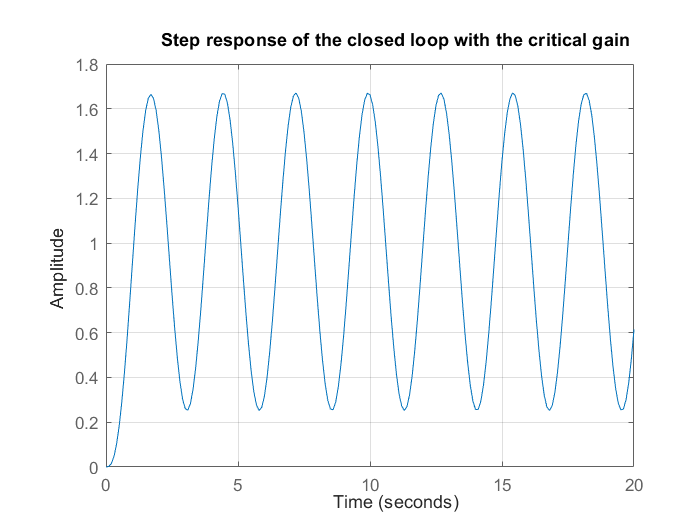

t=0:0.1:20;
step(Tcrit,t),grid
title('Step response of the closed loop with the critical gain')

The delay margin is the smallest value of the dead time  which pushes the system to the borderline of stability. The delay margin was defined in section as $T_{\textrm{dmin}} =\frac{\textrm{pm}\left\lbrack \textrm{rad}\right\rbrack }{\textrm{wc}\left\lbrack \frac{\textrm{rad}}{\sec }\right\rbrack }$. We can validate that here, again using the numbers extracted from ***margin.m ***and then adding the associated delay explicitly. As expected, sustained oscillation indicates closed-loop poles on the imaginary axis and emphasises that this is the maximum delay that the loop can cope with.

Td=(pm*pi/180)/wc

Td = 11.5608

L=L1*exp(-Td*s); % add delay to loop transfer function
Tdead=minreal(L/(1+L),0.001);

1 state removed.


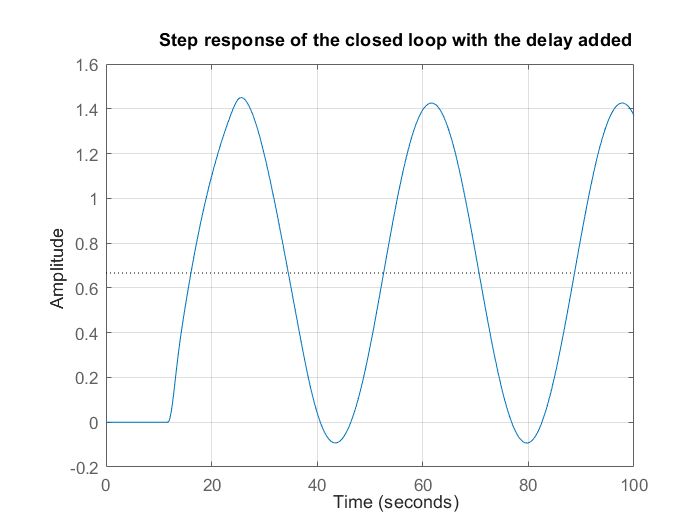

t1=0:0.1:100;
step(Tdead,t1),grid
title('Step response of the closed loop with the delay added')

#### Example 7.2

This example is similar to the previous and thus is presented with less explanation and more emphasis on just the code. The transfer function of the open loop is unstable.

                     
$$L_2 \left(s\right)=\frac{-5\left(1+3s\right)}{\left(1+5s\right)\left(1-s\right)}$$


We wish to investigate stability with a gain of unity and also how other values affect stability.

#### **7.2.1 Assess of poles**

From the pole positions, even though the open-loop system is unstable, the closed loop control system is stable and this is further evidenced in the step response.

disp('EXAMPLE 7.2.1')

EXAMPLE 7.2.1


clear
clf
disp('The transfer function of the open loop')

The transfer function of the open loop


s=zpk('s');
L2=-5*(1+3*s)/((1+5*s)*(1-s))       % unstable

L2 =
 
  3 (s+0.3333)
  -------------
  (s+0.2) (s-1)
 
Continuous-time zero/pole/gain model.
Model Properties


T2=minreal(L2/(1+L2),0.001)

T2 =
 
     3 (s+0.3333)
  -------------------
  (s+0.4597) (s+1.74)
 
Continuous-time zero/pole/gain model.
Model Properties



subplot(121)
pzmap(T2,'blue');
title('Pole-zero map of T2')
disp('The poles of the closed loop system')

The poles of the closed loop system


[pT2]=pzmap(T2)

pT2 =    -0.4597
   -1.7403


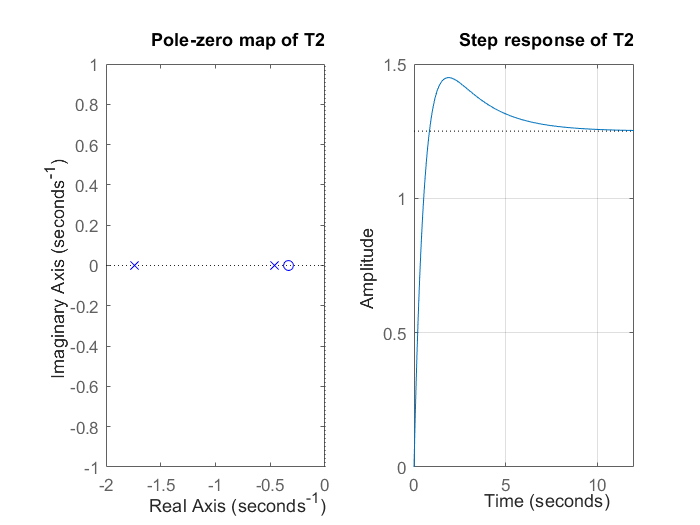


subplot(122)
step(T2),grid
title('Step response of T2')

#### 7.2.2 Using root-loci

Analyse the stability of the closed loop system and determine the critical gain based on the root locus curves. 

Note that the code opens a figure in a separate window and waits for you to use the crosshair to select the desired point, before the code continues to the next step.

disp('EXAMPLE 7.2.2')

EXAMPLE 7.2.2


clear
clf
disp('The transfer function of the open loop')

The transfer function of the open loop


s=zpk('s');
L2=-5*(1+3*s)/((1+5*s)*(1-s))       % unstable

L2 =
 
  3 (s+0.3333)
  -------------
  (s+0.2) (s-1)
 
Continuous-time zero/pole/gain model.
Model Properties


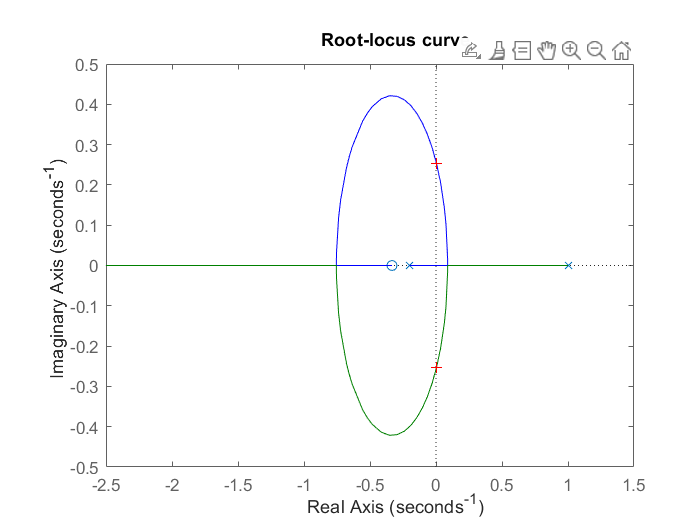

Select a point in the graphics window


selected_point = -0.0038 + 0.2457i

Kcrit2 = 0.2635


%Root locus curves
rlocus(L2)
title('Root-locus curve')
Kcrit2 = rlocfind(L2)


t=0:0.1:60;
disp('The transfer function of the closed loop')

The transfer function of the closed loop


T2=minreal(Kcrit2*L2/(1+Kcrit2*L2),0.001)

T2 =
 
      0.79046 (s+0.3333)
  ---------------------------
  (s^2 - 0.009543s + 0.06349)
 
Continuous-time zero/pole/gain model.
Model Properties


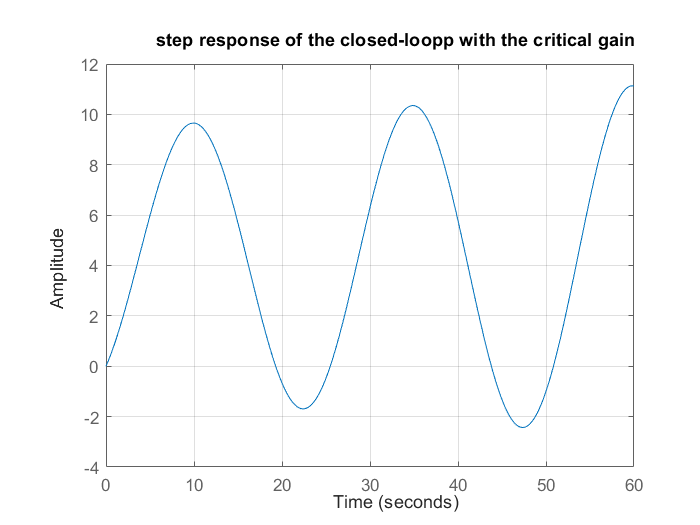

step(T2,t),grid
title('step response of the closed-loopp with the critical gain')

#### 7.2.3 Using the Nyquist stability criterion and margins

Analyse the stability of the closed loop system and determine the critical gain based on the Nyquist stability criterion.

- The closed loop is stable as the Nyquist diagram does encircle point -1+j0 counter-clockwise once as desired as there is one open-loop RHP pole.

- The step response plot validates that this method does indeed stabilise the system in the closedd-loop.

disp('EXAMPLE 7.2.3')

EXAMPLE 7.2.3


clear
clf
disp('The transfer function of the open loop')

The transfer function of the open loop


s=zpk('s');
L2=-5*(1+3*s)/((1+5*s)*(1-s))       % unstable

L2 =
 
  3 (s+0.3333)
  -------------
  (s+0.2) (s-1)
 
Continuous-time zero/pole/gain model.
Model Properties


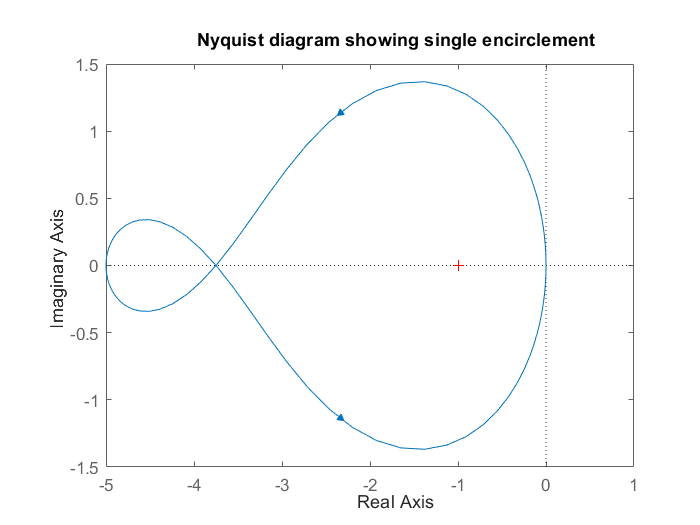


nyquist(L2)
title('Nyquist diagram showing single encirclement')


T2=minreal(L2/(1+L2),0.001)

T2 =
 
     3 (s+0.3333)
  -------------------
  (s+0.4597) (s+1.74)
 
Continuous-time zero/pole/gain model.
Model Properties


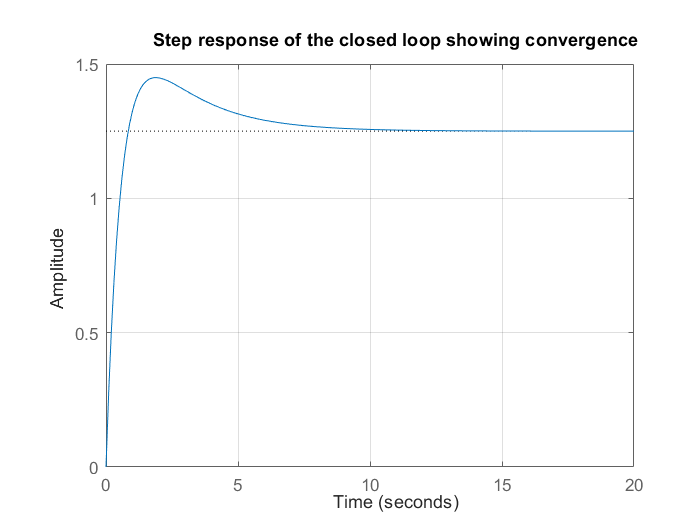

t=0:0.1:20;
step(T2,t),grid
title('Step response of the closed loop showing convergence')

The file ***margin.m*** can be used to determine the gain and phase margin and the associated cross-over frequencies. Again, as expected, the phase margin is positive which is associated to stable closed-loop behaviour.

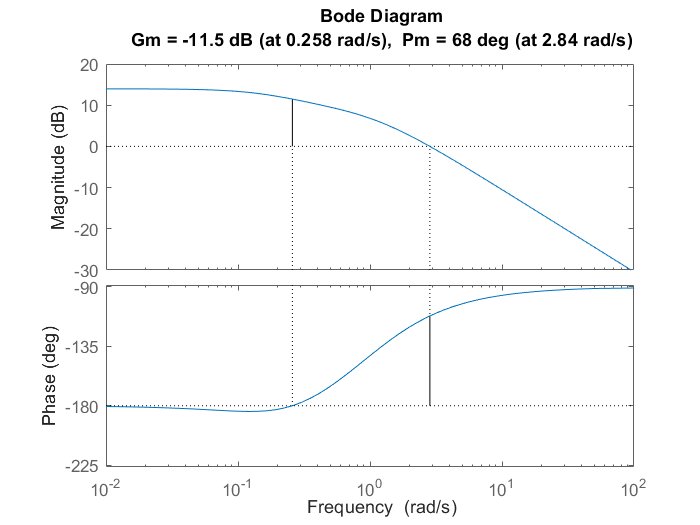

margin(L2)